# KUKA KR 60

Motion planning of a KUKA 6DoF (Kuka KR 60) robot.

## Introduction

Please, refer to following link for technical data: *http://www.wtech.com.tw/public/download/manual/kuka/KR_60HA.pdf*

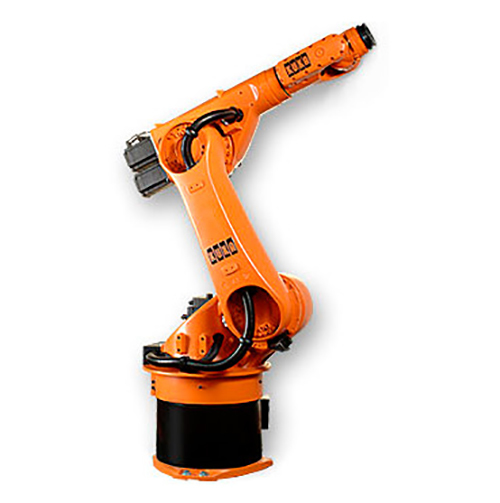    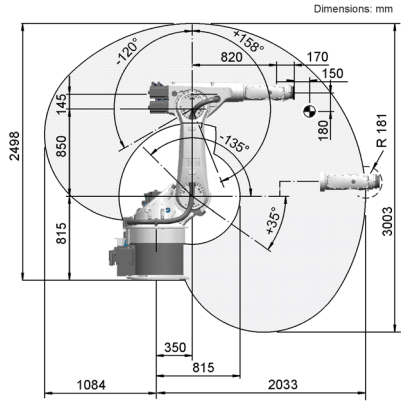

This manipulator is a 6-axis jointed-arm kinematic system, that consists of the following components:

- Base frame

- Rotating column

- Link arm

- Arm

- Triple-axis in-line wirst

All the joints are revolute, that means nor traslation or sliding linear motions between the bodies connected by this joint.

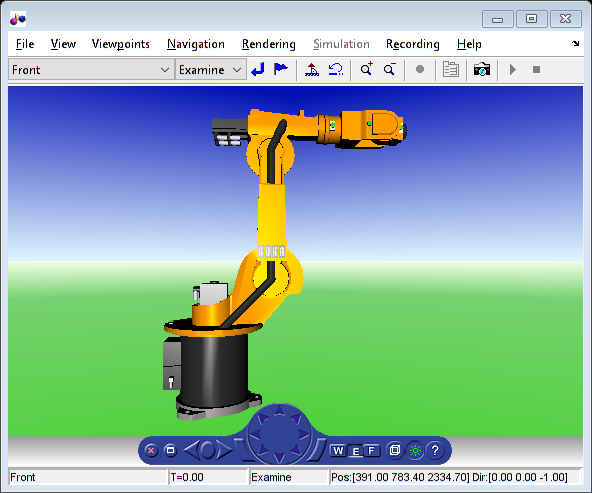

open('KukaKR6.wrl')

## Denavit-Hartenbergs parameters

Firstly, each link is assigned with a D-H coordinate frame, conform to the rules herebelow:

- The z-axis ($z_i$) is the rotation axis of each revolute joint.

- The x-axis ($x_i$) is the normal to the current z-axis ($z_i$) and the previous one ($z_{i-1}$) and must intersect the preious z-axis ($z_{i-1}$).

- The y-axis ($y_i$) is determined by the right-hand coordinate system.

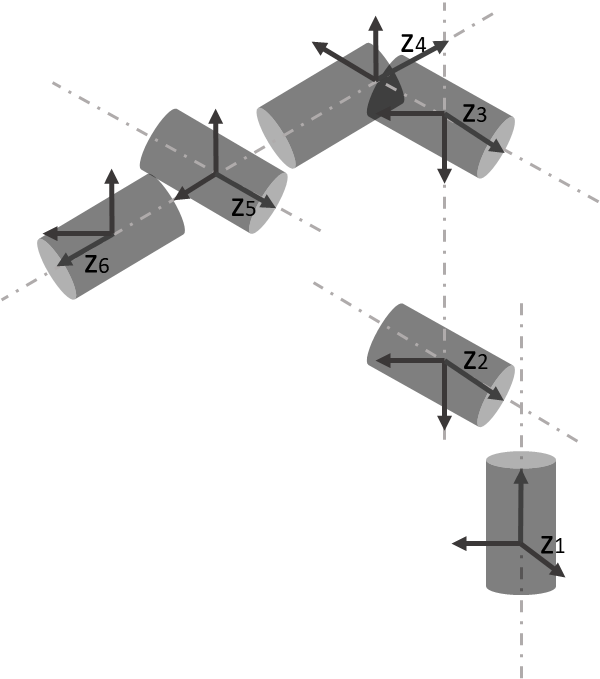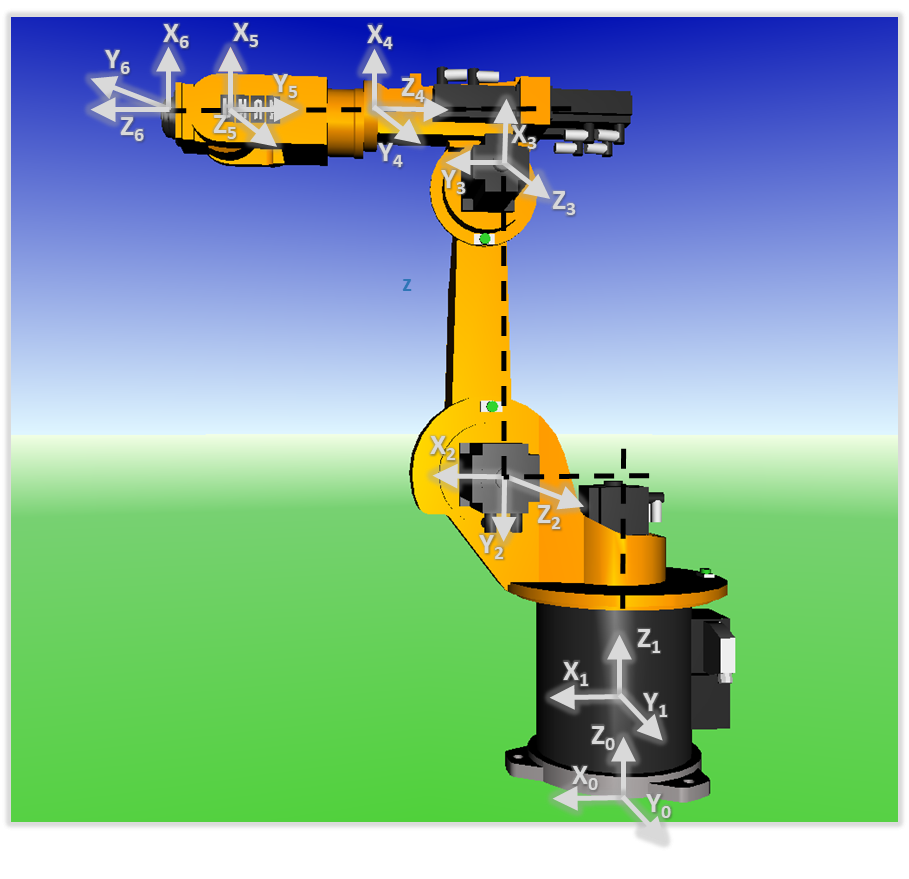

The Denavit-Hartenbergs parameters have been defined according to the DH convention, after having assigned a coordinate frame to each link of the Kuka KR 60. Hence, the D-H parameters can be computed as follow:

- $d_i$ is the distance from $x_{i-1}$ and $x_i$ along $z_i$

- $\theta_i$ (or offset) is the angle between $x_{i-1}$ and $x_i$ about $z_i$

- $a_i$ is the distance from $z_{i-1}$ to $z_i$ along $x_{i-1}$

- $a_i$ is the angle between $z_{i-1}$ to $z_i$ about $x_{i-1}$

dhParams = array2table([
  675,  350, -pi/2, 0;
    0,  850,     0, 0;
    0,  145,  pi/2, 0;
 -820,    0, -pi/2, 0;
    0,    0, -pi/2, 0;
  170,    0,     0, 0], 'VariableNames', {'d', 'a', 'alpha', 'offset'});
disp(dhParams);

     d       a      alpha     offset
    ____    ___    _______    ______

     675    350    -1.5708      0   
       0    850          0      0   
       0    145     1.5708      0   
    -820      0    -1.5708      0   
       0      0    -1.5708      0   
     170      0          0      0   



clear tableFormat;

## **Forward Kinematics**

The kinematics of the robot is solved using the Denavit-Hartenbergs' convention, which enables complete manipulation of the end-effector in three-dimensonal space.

The problem of the forward kinematics is to obtain the end-effector position with respect to a set of given joint angles $q_i$. The transformation from the current joint $i$ to the next is described by the matrix $A_{i+1}$:


$$A_{i+1} =\left\lbrack \begin{array}{cccc}
\cos \left(\theta \right) & -\sin \left(\theta \right)\cos \left(\alpha_{i+1} \right) & \sin \left(\theta \right)\sin \left(\alpha_{i+1} \right) & a_{i+1} \cos \left(\theta \right)\\
\sin \left(\theta \right) & \cos \left(\theta \right)\cos \left(\alpha_{i+1} \right) & -\cos \left(\theta \right)\sin \left(\alpha_{i+1} \right) & a_{i+1} \sin \left(\theta \right)\\
0 & \sin \left(\alpha_{i+1} \right) & \cos \left(\alpha_{i+1} \right) & d_{i+1} \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


The total transformation between the base of the robot and the end-effector is $T\;=A_1 A_2 A_3 A_4 A_5 A_6$. Each matrix is multiplied sequentially to get the homogeneous transform $T$, that describes the pose of the end-effector, for the specific joint configuration and DH parameters.

syms theta1 theta2 theta3 theta4 theta5 theta6;
syms alpha1 alpha2 alpha3 alpha4 alpha5 alpha6;
syms d1 d2 d3 d4 d5 d6;
syms a1 a2 a3 a4 a5 a6;

ca1 = cosi(dhParams(1, :).alpha);   sa1 = sini(dhParams(1, :).alpha);
ca2 = cosi(dhParams(2, :).alpha);   sa2 = sini(dhParams(2, :).alpha);
ca3 = cosi(dhParams(3, :).alpha);   sa3 = sini(dhParams(3, :).alpha);
ca4 = cosi(dhParams(4, :).alpha);   sa4 = sini(dhParams(4, :).alpha);
ca5 = cosi(dhParams(5, :).alpha);   sa5 = sini(dhParams(5, :).alpha);
ca6 = cosi(dhParams(6, :).alpha);   sa6 = sini(dhParams(6, :).alpha);

A1 = [cos(theta1)   -sin(theta1)*ca1    sin(theta1)*sa1     a1*cos(theta1);
    sin(theta1)     cos(theta1)*ca1     -cos(theta1)*sa1    a1*sin(theta1);
    0               sa1                 ca1                 d1;
    0               0                   0                   1];
disp('A1 = '); disp(A1);

A1 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & a_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right) & a_{1}\,\sin\left(\theta_{1}\right)\\ 0 & -1 & 0 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


A2 = [cos(theta2)   -sin(theta2)*ca2    sin(theta2)*sa2     a2*cos(theta2);
    sin(theta2)     cos(theta2)*ca2    -cos(theta2)*sa2     a2*sin(theta2);
    0               sa2                 ca2                 d2;
    0               0                   0                   1];
disp('A2 = '); disp(A2);

A2 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & a_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & a_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & d_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


A3 = [cos(theta3)   -sin(theta3)*ca3    sin(theta3)*sa3     a3*cos(theta3);
    sin(theta3)     cos(theta3)*ca3    -cos(theta3)*sa3     a3*sin(theta3);
    0               sa3                 ca3                 d3;
    0               0                   0                   1];
disp('A3 = '); disp(A3);

A3 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & 0 & \sin\left(\theta_{3}\right) & a_{3}\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & 0 & -\cos\left(\theta_{3}\right) & a_{3}\,\sin\left(\theta_{3}\right)\\ 0 & 1 & 0 & d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


A4 = [cos(theta4)	-sin(theta4)*ca4    sin(theta4)*sa4     a4*cos(theta4);
    sin(theta4)     cos(theta4)*ca4    -cos(theta4)*sa4     a4*sin(theta4);
    0               sa4                 ca4                 d4;
    0               0                   0                   1];
disp('A4 = '); disp(A4);

A4 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & 0 & -\sin\left(\theta_{4}\right) & a_{4}\,\cos\left(\theta_{4}\right)\\ \sin\left(\theta_{4}\right) & 0 & \cos\left(\theta_{4}\right) & a_{4}\,\sin\left(\theta_{4}\right)\\ 0 & -1 & 0 & d_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


A5 = [cos(theta5)   -sin(theta5)*ca5    sin(theta5)*sa5     a5*cos(theta5);
    sin(theta5)     cos(theta5)*ca5    -cos(theta5)*sa5     a5*sin(theta5);
    0               sa5                 ca5                 d5;
    0               0                   0                   1];
disp('A5 = '); disp(A5);

A5 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{5}\right) & 0 & -\sin\left(\theta_{5}\right) & a_{5}\,\cos\left(\theta_{5}\right)\\ \sin\left(\theta_{5}\right) & 0 & \cos\left(\theta_{5}\right) & a_{5}\,\sin\left(\theta_{5}\right)\\ 0 & -1 & 0 & d_{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


A6 = [cos(theta6)	-sin(theta6)*ca6    sin(theta6)*sa6     a6*cos(theta6);
    sin(theta6)     cos(theta6)*ca6    -cos(theta6)*sa6     a6*sin(theta6);
    0               sa6                 ca6                 d6;
    0               0                   0                   1];
disp('A6 = '); disp(A6);

A6 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{6}\right) & -\sin\left(\theta_{6}\right) & 0 & a_{6}\,\cos\left(\theta_{6}\right)\\ \sin\left(\theta_{6}\right) & \cos\left(\theta_{6}\right) & 0 & a_{6}\,\sin\left(\theta_{6}\right)\\ 0 & 0 & 1 & d_{6}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


syms nx ox ax px;
syms ny oy ay py;
syms nz oz az pz;

T = [nx, ox, ax, px;
    ny, oy, ay, py;
    nz, oz, az, pz;
    0, 0, 0, 1];
disp('T = '); disp(T);

T = 


$$\left(\begin{array}{cccc} \mathrm{nx} & \mathrm{ox} & \mathrm{ax} & \mathrm{px}\\ \mathrm{ny} & \mathrm{oy} & \mathrm{ay} & \mathrm{py}\\ \mathrm{nz} & \mathrm{oz} & \mathrm{az} & \mathrm{pz}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


Tx = A1*A2*A3*A4*A5*A6;
nx = Tx(1, 1)

$$nx = \begin{array}{l} \sin\left(\theta_{6}\right)\,\left(\cos\left(\theta_{4}\right)\,\sin\left(\theta_{1}\right)-\sin\left(\theta_{4}\right)\,\sigma_{1}\right)-\cos\left(\theta_{6}\right)\,\left(\cos\left(\theta_{5}\right)\,\left(\sin\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)+\cos\left(\theta_{4}\right)\,\sigma_{1}\right)+\sin\left(\theta_{5}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right) \end{array}$$

ny = Tx(2, 1)

$$ny = \begin{array}{l} \cos\left(\theta_{6}\right)\,\left(\cos\left(\theta_{5}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{4}\right)\,\sigma_{1}\right)-\sin\left(\theta_{5}\right)\,\left(\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)\right)-\sin\left(\theta_{6}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{4}\right)+\sin\left(\theta_{4}\right)\,\sigma_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right) \end{array}$$

nz = Tx(3, 1)

$$nz = -\cos\left(\theta_{6}\right)\,\left(\sin\left(\theta_{5}\right)\,\left(\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\right)+\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\left(\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\right)\right)-\sin\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right)\,\left(\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\right)$$

ox = Tx(1, 2)

$$ox = \begin{array}{l} \cos\left(\theta_{6}\right)\,\left(\cos\left(\theta_{4}\right)\,\sin\left(\theta_{1}\right)-\sin\left(\theta_{4}\right)\,\sigma_{1}\right)+\sin\left(\theta_{6}\right)\,\left(\cos\left(\theta_{5}\right)\,\left(\sin\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)+\cos\left(\theta_{4}\right)\,\sigma_{1}\right)+\sin\left(\theta_{5}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right) \end{array}$$

oy = Tx(2, 2)

$$oy = \begin{array}{l} -\cos\left(\theta_{6}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{4}\right)+\sin\left(\theta_{4}\right)\,\sigma_{1}\right)-\sin\left(\theta_{6}\right)\,\left(\cos\left(\theta_{5}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{4}\right)\,\sigma_{1}\right)-\sin\left(\theta_{5}\right)\,\left(\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right) \end{array}$$

oz = Tx(3, 2)

$$oz = \sin\left(\theta_{6}\right)\,\left(\sin\left(\theta_{5}\right)\,\left(\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\right)+\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\left(\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\right)\right)-\cos\left(\theta_{6}\right)\,\sin\left(\theta_{4}\right)\,\left(\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\right)$$

ax = Tx(1, 3)

$$ax = \sin\left(\theta_{5}\right)\,\left(\sin\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)+\cos\left(\theta_{4}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\right)\right)-\cos\left(\theta_{5}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\right)$$

ay = Tx(2, 3)

$$ay = -\sin\left(\theta_{5}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{4}\right)\,\left(\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\right)\right)-\cos\left(\theta_{5}\right)\,\left(\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)$$

az = Tx(3, 3)

$$az = \cos\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)\,\left(\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\right)-\cos\left(\theta_{5}\right)\,\left(\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\right)$$

px = Tx(1, 3)

$$px = \sin\left(\theta_{5}\right)\,\left(\sin\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)+\cos\left(\theta_{4}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\right)\right)-\cos\left(\theta_{5}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\right)$$

py = Tx(2, 3)

$$py = -\sin\left(\theta_{5}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{4}\right)\,\left(\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\right)\right)-\cos\left(\theta_{5}\right)\,\left(\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)$$

pz = Tx(3, 3)

$$pz = \cos\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)\,\left(\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\right)-\cos\left(\theta_{5}\right)\,\left(\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\right)$$

The function `solve.forwardKinematics` solves the forward kinematics problem for a set of given joint angles `q`, by sequentially multipling each joint matrix $A_i$ ($T\;=A_1 A_2 A_3 A_4 A_5 A_6$), where $A_i$ is computed by `solver.computeT()`.

## **Inverse Kinematics**

Knowing the desired end-effector position, it is possible by means of the inverse kinematics, to get the required joint angles to reach the target pose.

The inverse kinematics analysis can be done by sequentially multiplying each inverse matrix $A_i$ on the left side of the equation described above ($T\;=A_1 A_2 A_3 A_4 A_5 A_6$). The final solution ($\theta_1 ,\theta_2 ,\theta_3 ,\theta_4 ,\theta_5 ,\theta_6$) is given by equalizing the corresponding elements of both equation ends.


$$A_1^{-1} T=A_2 A_3 A_4 A_5 A_6$$


firstEq = inv(A1)*T;
disp(firstEq);

$$\begin{array}{l} \left(\begin{array}{cccc} \frac{\mathrm{nx}\,\cos\left(\theta_{1}\right)}{\sigma_{1}}+\frac{\mathrm{ny}\,\sin\left(\theta_{1}\right)}{\sigma_{1}} & \frac{\mathrm{ox}\,\cos\left(\theta_{1}\right)}{\sigma_{1}}+\frac{\mathrm{oy}\,\sin\left(\theta_{1}\right)}{\sigma_{1}} & \frac{\mathrm{ax}\,\cos\left(\theta_{1}\right)}{\sigma_{1}}+\frac{\mathrm{ay}\,\sin\left(\theta_{1}\right)}{\sigma_{1}} & \frac{\mathrm{px}\,\cos\left(\theta_{1}\right)}{\sigma_{1}}-a_{1}+\frac{\mathrm{py}\,\sin\left(\theta_{1}\right)}{\sigma_{1}}\\ -\mathrm{nz} & -\mathrm{oz} & -\mathrm{az} & d_{1}-\mathrm{pz}\\ \frac{\mathrm{ny}\,\cos\left(\theta_{1}\right)}{\sigma_{1}}-\frac{\mathrm{nx}\,\sin\left(\theta_{1}\right)}{\sigma_{1}} & \frac{\mathrm{oy}\,\cos\left(\theta_{1}\right)}{\sigma_{1}}-\frac{\mathrm{ox}\,\sin\left(\theta_{1}\right)}{\sigma_{1}} & \frac{\mathrm{ay}\,\cos\left(\theta_{1}\right)}{\sigma_{1}}-\frac{\mathrm{ax}\,\sin\left(\theta_{1}\right)}{\sigma_{1}} & \frac{\mathrm{py}\,\cos\left(\theta_{1}\right)}{\sigma_{1}}-\frac{\mathrm{px}\,\sin\left(\theta_{1}\right)}{\sigma_{1}}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\cos\left(\theta_{1}\right)}^{2}+{\sin\left(\theta_{1}\right)}^{2} \end{array}$$

secondEq = A2*A3*A4*A5*A6;
disp(secondEq);

It can be easily noticed how this equations can be heavy to solve. Therefore this approach can be replaced by easier iterative algorithms.

The inverse kinematics problem can be viewed as finding roots of a non linear equation $T\left(\theta \right)=X$, where $X$is the homogeneous transform of the target configuration. The equation can be rewritten in the form $T\left(\theta \right)-X=0$, whose roots can be found using the Newton-Rapshon method. It's worth mentioning how this method can be applied to find the roots of a continuous and differentiable function. Considering, for example, the function $x_d -f\left(\theta \right)$, and the initial estimate of the root $\theta_0$. The method searches the nearest root, by using the tangent of $x_d -f\left(\theta \right)$, to improve the estimate of the root. The expression that gives the $x_{n+1}$ from $x_n$ is entirely determined by *known *properties the function at  $x_n$: 


$$x_{n+1} =x_n -\frac{f\left(x_n \right)}{f\prime \left(x_n \right)}=\frac{x_d -f\left(\theta_n \right)}{\left(\frac{\delta f}{\delta \theta }\left(\;\theta_n \right)\right)}$$


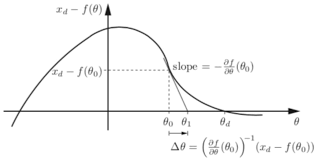

Though Newton-Raphson method is widely used, it doesn't guarantee the global convergence. Furthermore, also the equation solvability (target pose of end-effector and orientation) is not necessarily guardanteed. In 2009, a new technique based on the Levenberg-Marquardt was hence proposed [[1]](#M_1850E4CE). [[2]](#M_44DFAC54) used the Gauss-Newton with the Levenberg-Marquardt method as numerical optimization method, that, combined with an online learning approach, allows to reach the desired pose quicker on average. While the online learning approach is to be considered out of the scope of this work, the numerical method is adopted.

The Levenber-Marquardt method is an iterative, optimization method, that combines the Gauss-Newton method and the gradrient descent to find a solution. At each step, basing on the value of the parameter $\lambda \;$(a non negative damiping factor), the algorithm chooses between Gauss-Newton and the gradient descend, to update the solution. The Gauss-Newton is more accurate and faster than the gradient descent when close to the minimum error. Therefore, the algorithm will tend to the GN algorithm as soon as possible.

Summarising, the Levenberg-Marquardt algorithm adaptively varies the parameter updates between the gradient descent update and the Gauss-Newton update:


$$\left(J^T \textrm{WJ}+\lambda \;I\right)h=J^T {\textrm{Wy}}_{\textrm{err}}$$


where $h$ is the parameter updated and $y_{\textrm{err}} =x_d -x\left(q\right)$

Hence: $h=\frac{J^T {\textrm{Wy}}_{\textrm{err}} }{J^T \textrm{WJ}+\lambda \;I}$.

After updating the solution $q_{\textrm{update}} =q+h^T$,  $\lambda \;$is updated:

- as the solution improves ($y_{\textrm{errNew}} <y_{\textrm{err}}$), $\lambda$ is decreased and q is updated ($q=q_{\textrm{update}}$): the Levenberg-Marquardt method approaches the Gauss-Newton method, and the solution typically accelerates to the local minimum, as explained in [[3]](#M_48B7123D).

- if $y_{\textrm{errNew}} >y_{\textrm{err}}$, $\lambda$ is increased, and the solution diverges.

Please note, the weighting matrix is set to be simply an identity matrix.

The `solver.inverseKinematics()` implements this technique to find the desired configuration for the joint angles. The initial configuration `q` is the home configuration. A maximum number of iteration is provided to limit the computational cost at runtime: if no solution can be found in the range defined by the tolerance (default, ${10}^{-6}$), the last computed solution is returned. If the method doesn't converge to a solution, and all the calculated configurations have been rejected, the status is failed.

## **Inverse Dynamic**

Solving the inverse dynamic means calculate the joint forces and torques necessary to create the desired joint acceleration at the current joint position and velocities.

The Newton-Euler method allows to describe the dynamic motion of a rigid body system, in terms of forces and torques. In contrast with the Euler-Lagrange method (energy based) that considers the system as a whole, the NE makes use of one equation for each link, that is evualuated in a numeric form and recursive way. In particular:


$$\begin{array}{l}
\textrm{Newton}\to \;\sum_i f_i =\frac{d}{\textrm{dt}}\left({\textrm{mv}}_c \right)\\
\textrm{Euler}\to \sum_i \mu_i =\frac{d}{\textrm{dt}}\left(I\omega \right)=I\dot{\omega} +\omega \times I\omega 
\end{array}$$


The algorithm can be splitted in two steps: *forward iteration* and *backward iteration *[[4]](#M_0F3EC533). 

**The forward iteration**

Given $\theta ,\dot{\theta} ,\ddot{\theta}$, for each link (from the base to the end-effector):

- Calculate $\omega_i \;$as sum of $\omega_{i-1}$(expredsed in frame $i$) and a term due to $\dot{\theta_i }$:$\omega_i =R\left(\omega_{i-1} +z_0 \theta_i \right)$

- Calculate $\dot{\omega_i } \;$as sum of ${\dot{\omega} }_{i-1}$(expressed in frame $i$) and a term due to $\ddot{\theta_i } \;$and the velocity product term due to $\omega_i$and $\dot{\theta_i }$: ${\dot{\omega \;} }_i =R\left({\dot{\omega \;} }_{i-1} +z_0 \dot{\theta_i } \;+\omega_{i-1} \times z_0 \dot{\theta_i } \;\right)$

- Calculate $\ddot{\theta_i } \;$ as sum of a term due to ${\dot{\omega} }_i$ and a term due to $\omega_i$:$\ddot{\theta_i } \;={\dot{\omega \;} }_i \times p^* +\omega_i \times \omega_i \times p^* +R\;G$

**The backward iteration**

Given $\theta ,\dot{\theta} ,\ddot{\theta}$, for each link (from the end-effector to the base):

- Calculate $F_i$ as sum of $F_{i+1}$ and the external forces. $F_i =M_j \left(\dot{\omega_j } \times r+\omega_j \times \omega_j \times r+{\dot{\theta} }_j \right)+\;\sum_{j=i+1}^n f_j$

- Calculate $\tau_i$ as the component of $F_i$ along the joint skew axis: $\tau_j =I\dot{\omega_j } +\omega_j \times I\omega_j$ [[5]](#M_BCC0813E)

For more details about the algorithms, please refer to its implementation in `solver.inverseDynamics()`.

## Trajectory Planning

The trajectory planning problem consists in find a time series of successive joint angles that allows to achieve a task, a target configuration. 

### **Comparison between task space and joint space**

Joint-space description: the description of the motion to be made by the robot by its joint values. The motion between the two points is unpredictable.

Operational-space description: the description of the motion is in the operational space (cartesian or working space). The motion between two points is known and controllable at all time, but it is difficult to ensure that singuarities does not occur.

**Task space**

- Calculate the path from the initial point to the final point

- Assing a total time $T_{\textrm{path}}$to traverse the path

- Discretize the points in time and space

- Blend a continuous time function between these points

- Solve inverse kinematics at each step

**Joint space**

- Calculate the inverse kinematic solution from the initial point to the final point

- Assign the total time $T_{\textrm{path}}$using maximal velocities in joints

- Discretize the individual joint trajectories in time

- Blend a continuous function between these point

A small summary of the pro (OK) and contra (NO) of each space trajectory is herebelow described.


$$\matrix{
\textbf{Operational Space Trajectory} & \textbf{Joint Space Trajectory}                               \cr
\text{OK: Motion is predictable} & \text{NO: Motion not predictable} \cr
\text{OK: Collision-free path obtainable}    & \text{NO: Collision-free path not guaranteed}                             \cr
\text{NO: IK computed each time step}        & \text{OK: IK computed only once}                                     \cr
\text{NO: Unknown how to set total time}    & \text{OK: Joint and velocity constraints} \cr
\text{NO: Actuator motion not always smooth} & \text{OK: Actuator motion smooth} \cr
}$$


### Polynomial trajectory

In order to generate the trajectory, to move from the initial configuration to the target configuration, the path between the two waypoints shall be defined.

**Cubic Polynomial**

For each joint a function is required: its initial value at $t_0$ coincides with the initial configuration, while the final value at $t_F$ is the desired goal position. The four constraints used in the polynomial definition are $\theta \left(0\right)=\theta_0 ;\;\theta \left(t_F \right)=\theta_f ;\dot{\theta} \left(0\right)=0;\dot{\theta} \left(t_F \right)=0$. Hence:


$$\begin{array}{l}
\theta \left(t\right)=a_0 +a_1 t+a_2 t^2 +a_3 t^3 \\
\dot{\theta} \left(t\right)=a_1 +{2a}_2 t+{3a}_3 t^2 \\
\ddot{\theta} \left(t\right)=a_2 +{6a}_3 t
\end{array}$$


syms q0 qf v0 vf t;
c = [q0; v0; 0; 0];
T0 = [1 t; 0 1];
invTF = [3/t^2, -1/t;
    -2/t^3,  1/t^2];
c(3:4) = invTF * ([qf; vf] - T0*c(1:2));
disp(c);

$$\left(\begin{array}{c} q_{0}\\ v_{0}\\ \frac{v_{0}-\mathrm{vf}}{t}-\frac{3\,\left(q_{0}-\mathrm{qf}+t\,v_{0}\right)}{t^{2}}\\ \frac{2\,\left(q_{0}-\mathrm{qf}+t\,v_{0}\right)}{t^{3}}-\frac{v_{0}-\mathrm{vf}}{t^{2}} \end{array}\right)$$

Please, refer to the function `trajectory.cubicPolynomial `[[here](matlab:open('./srcs\matlab\+trajectory\cubicPolynomial.m'))] for the implementation.

**Quintic Polynomial**

To consider position, velocity and acceleration at the beginning and end of a path segment, a quintic polynomial is required:


$$\begin{array}{l}
\theta \left(t\right)=a_0 +a_1 t+a_2 t^2 +a_3 t^3 +a_4 t^4 +a_5 t^5 \\
\dot{\theta} \left(t\right)=a_1 +{2a}_2 t+{3a}_3 t^2 +{4a}_4 t^3 +5a_5 t^4 \\
\ddot{\theta} \left(t\right)={2a}_2 +{6a}_3 t+12a_4 t^2 +20a_5 t^3 
\end{array}$$


syms q0 qf v0 vf a0 af t;
c = [q0; v0; a0; 0; 0; 0];
T0 = [1 t t^2; 0 1 2*t; 0 0 2];
invTF = [10/t^3, -4/t^2,  1/(2*t);
    -15/t^4,  7/t^3, -1/t^2;
    6/t^5, -3/t^4,  1/(2*t^3)];
c(4:6) = invTF * ([qf; vf; af] - T0*c(1:3));
disp(c);

$$\begin{array}{l} \left(\begin{array}{c} q_{0}\\ v_{0}\\ a_{0}\\ \frac{4\,\sigma_{2}}{t^{2}}-\frac{2\,a_{0}-\mathrm{af}}{2\,t}-\frac{10\,\sigma_{1}}{t^{3}}\\ \frac{2\,a_{0}-\mathrm{af}}{t^{2}}-\frac{7\,\sigma_{2}}{t^{3}}+\frac{15\,\sigma_{1}}{t^{4}}\\ \frac{3\,\sigma_{2}}{t^{4}}-\frac{2\,a_{0}-\mathrm{af}}{2\,t^{3}}-\frac{6\,\sigma_{1}}{t^{5}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{0}\,t^{2}+v_{0}\,t+q_{0}-\mathrm{qf}\\ \sigma_{2}=v_{0}-\mathrm{vf}+2\,a_{0}\,t \end{array}$$

Please, refer to the function `trajectory.quinticPolynomial()` [[here](matlab:open('./srcs\matlab\+trajectory\quinticPolynomial.m'))] for the implementation.

## **lib_Solver **

The library `lib_Solver` implements the system blocks, that call the respective function described above.

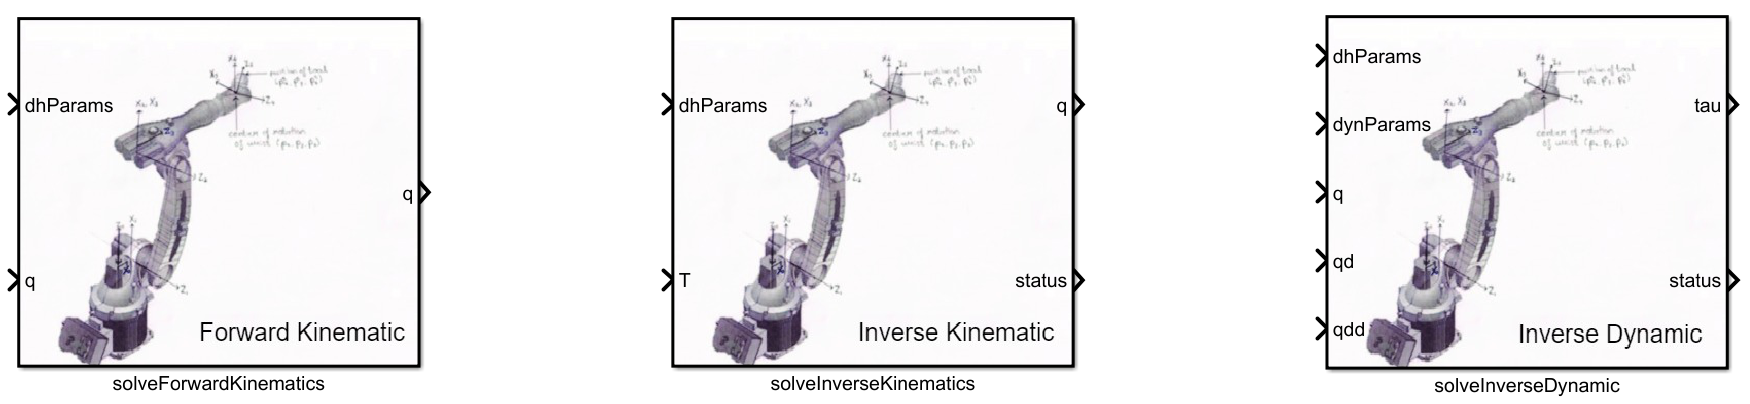

#### solveForwardKinematics lib

The `solveForwardKinematics` system block gets in input the DH parameters of the system and the joint configuration $q_{\left\lbrack 1\textrm{x6}\right\rbrack }$, and outputs the link positions.

#### solveInverseKinematics lib

The `solveInverseKinematics` system block computes, by means of DH parameters and the desired end-effector position in the form of the homogeneous transformation $T_{\left\lbrack 4\textrm{x4}\right\rbrack }$, the required joint angles $q_{\left\lbrack 1\textrm{x6}\right\rbrack }$.

#### solveInverseDynamic lib

The `solveInverseDynamic` system block is responsible for calculating the torque required for the specific joint configuration. Following input parameters are required:

- DH parameters

- Dynamic parameters (Inertia matrix, Mass, External Forces)

- joint angles

- joint velocities

- joint accelerations

## **TrajectoryGenerator System Object**

The Matlab System Object `core.trajectoryGenerator` [[here](matlab:open('./srcs\matlab\+core\TrajectoryGenerator.m'))] implements specific methods and properties for modeling the trajectory generation algorithm. By means of a cubic or a quintic polynomial, the path that connects pre-defined waypoints is computed. 

The System Object implements a custom mask that allow the user to easily configure the desired trajectory:

- SolverSpace: whether `TaskSpace` or `JointSpace`. For the joint space the orientations, if defined, are automatically integrated.

- Method: whether `Cubic` or `Quintic Polynomial`. If quintic is selected, the popup allow the user to select the desired acceleration, otherwise is hidden.

- Waypoints: the set of waypoints.

- TimePoints: the set of time points associated to the waypoints.

- Velocity: the desired velocities, associated to the waypoints.

- Acceleration: the desired acceleration, associated to the waypoints (available only for quintic polynomial).

- (Experimental - still wip) Integrate orientations using SLERP.

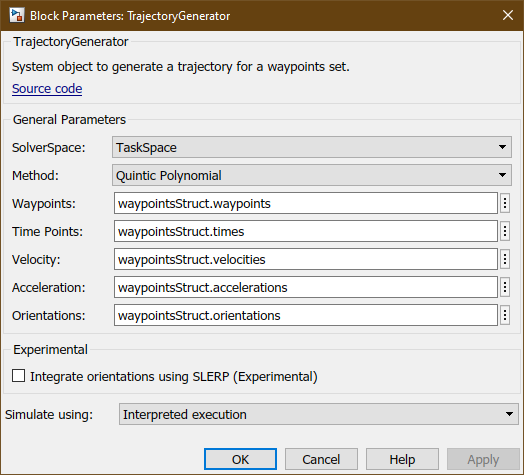

## KukaSimModel

The model "*KukaSimModel"* simulates the motion planning of the Kuka KR, described by the DH parameters and dynamic parameters loaded in the workspace.  The robot will follow the trajectory generated at run time for the set of waypoints present in the workspace.

open_system('KukaSimModel.slx');

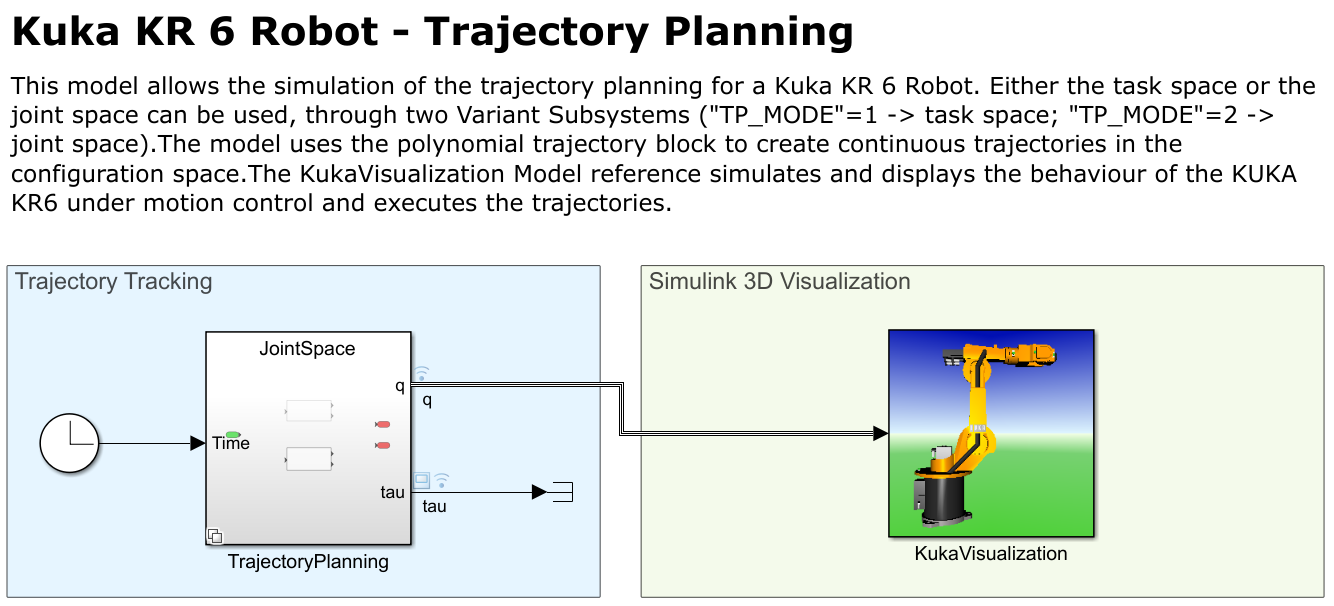

The model can be splitted, architecturally speaking, into two parts: the "*TrajectoryPlanning*" and the *"KukaVisualization"* subsystem. While the former is responsible for the proper motion planning, the latter displays the movement of the KUKA KR 60 by means of the Simulation 3D Animation toolbox. 

### TrajectoryPlanning

The "*TrajectoryPlanning"* subsystem is a Variant Subsystem, that enables whether the "*TaskSpace*" or the "*JointSpace*" subsystem, basing on the value that the variable `TP_MODE` is assigned.

- `TP_MODE = 1 `for the simulation in the Task Space;

- `TP_MODE = 2 `for the simulation in the Joint Space.

#### TaskSpace Subsystem

#### 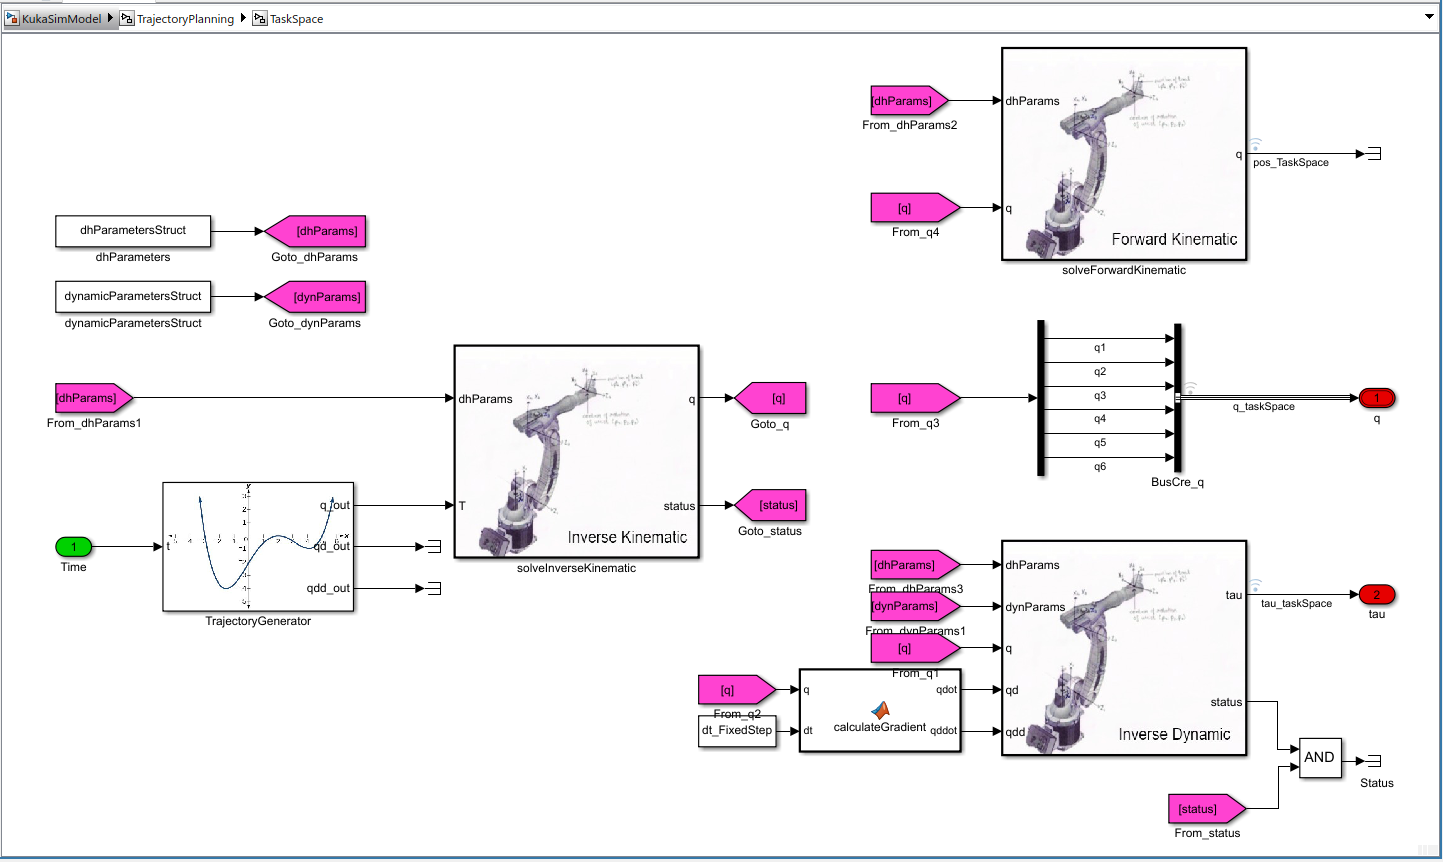

When the TaskSpace is chosen, the main steps executed are:

- Calculate the Trajectory basing on the waypoints selected and its method (cubic or polynomial).

- The required position at the specific time step is returned and passed through the `solveInverseKinematics`, in the form of homogeoneous transform T.

- The `solveInverseKinematics` library calcultes than the required joint angles position to let the end-effector reach the desired position.

- The joint angles `q` are hence passed to the inverse dynamic block that calculates the necessary torques $\tau_{\left\lbrack 6\textrm{x1}\right\rbrack }$. In order to calculate the joint velocities and the joint acceleration, the gradient of the position and the velocities are respectively calculated.

- The joint angles q are hence passed to the forward kinematic in order to calculate the real position of the links. The variable `pos_TaskSpace` can be then plotted in order to check and verify the real movement of the robot.

- The joint angles q are hence propagated in form of a bus object `BusCre_q`, using a demux to pass the each vector element with the proper name to the bus`.`

#### **JointSpace Subsystem**

### 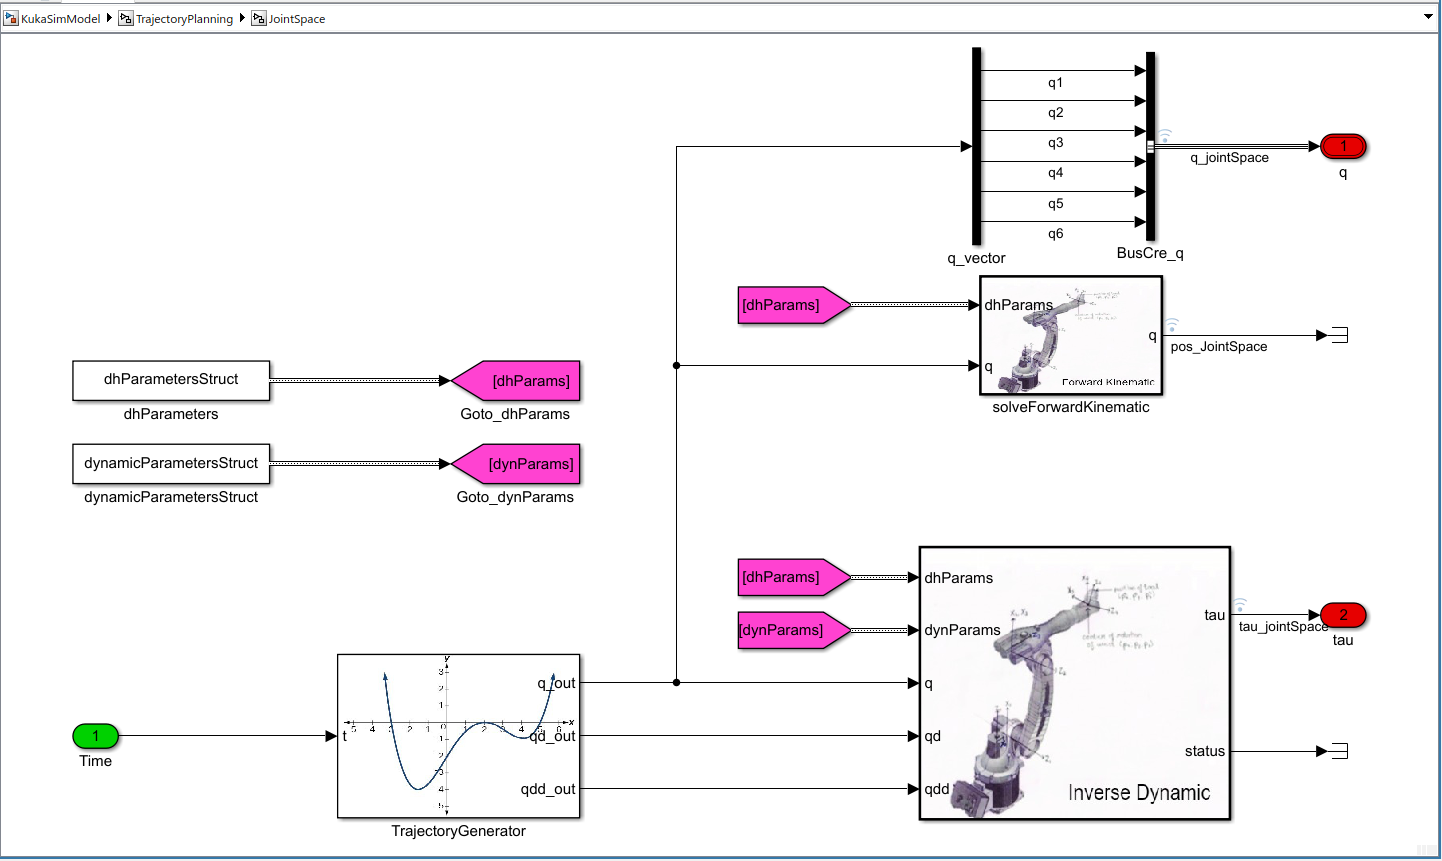

The Trajectory Generation when the JointSpace is selected, require the InverseKinematics to be calculated before the TrajectoryGenerator is executed.

This means:

-  An *InitFcn* callback is configured to run the Inverse Kinematics on the waypoints

- The result `jointWaypoints `is fed into the TrajectoryGenerator object, that calculates the required joint position at the specific time step, in order to follow the defined path. 

- The calculated joint angles, as well as the velocities and the accelerations are passed to the Inverse Dynamic block for the torque computation.

- The calculated joint angles are hence passed to the forward kinematic in order to calculate the real position of the links. The variable `pos_JointSpace` can be then plotted in order to check and verify the real movement of the robot.

- The joint angles q are hence propagated in form of a bus object `BusCre_q`, using a demux to pass the each vector element with the proper name to the bus`.`

### KukaVisualization Subsystem

The KukaVisualization Subsystem sets the calculated joint angles, for the wrl visualisation, using the Simulink 3D Animation toolbox.

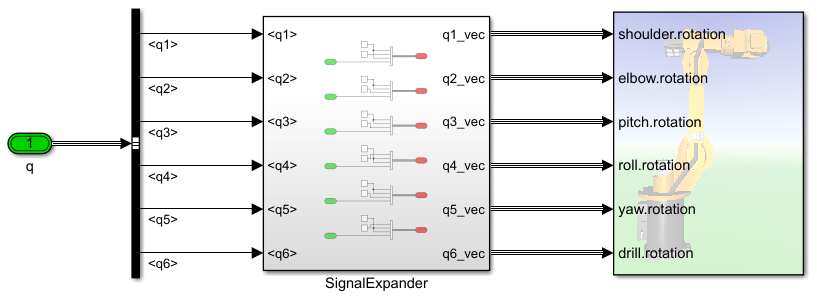

The inport q is a specific bus `Bus_q `defined in the workspace:

if exist("IsSixAxesRobotInitialized", 'var')
    disp('Bus_q:'); disp(Bus_q);
    disp('Bus_q.Elements(1):'); disp(Bus_q.Elements(1));
end

Bus_q:
  Bus with properties:

                  Description: ''
                    DataScope: 'Auto'
                   HeaderFile: ''
                    Alignment: -1
    PreserveElementDimensions: 0
                     Elements: [6×1 Simulink.BusElement]



Bus_q.Elements(1):
  BusElement with properties:

              Name: 'q1'
        Complexity: 'real'
        Dimensions: 1
          DataType: 'double'
               Min: []
               Max: []
    DimensionsMode: 'Fixed'
              Unit: ''
       Description: ''



The *SignalExpander* creates a vector for each joint angle, that defines in which axes shall the rotation take place.

## **Simulation**

The simulation needs a specific environment to be setup. Following steps are hence necessary:

- Add Matlab paths where sources are inside

- Load DH parameters

- Load Dynamic parameters

- Load BusObjects

- Load Waypoints

- Set Variant Subsystem

- Load simulation model.

In the following section the user can define some configuration to run the simulation:

- `Model` name ("KukaSimModel" as default);

- `Space`: whether TaskSpace or JointSpace;

- `Trajectory`: the gen_waypointSet script to run for the generation of the waypointStruct;

- `Polynomial`: whether quintic or cubic polynomial;

- `Visualize`: whether the wrl model shall be opened.

### **Run setup**

% Set configuration
colors.red    = [.64 .02 .03];
colors.blue   = [.02 .52 .51];
colors.green  = [.04 .79 .17];

clear config; % ensure clear config
config.modelName    = 'KukaSimModel';
config.space        = enum.SpaceEnum.TaskSpace;
config.trajectory   = 5;
config.polynomial   = "Quintic Polynomial";
config.visualize    = false;

% Startup setup
startup;

|    Startup KukaKR6...    |
-> Reloading D-H parameters...
-> Reloading Dynamic parameters...
Mass: 
   26.9797
   15.9204
   25.8524
    4.0885
    1.6154
    0.0160

-> Reloading Bus Objects...
-> Setting Variant Subsystem...
TP_MODE=1->["TaskSpace"]
-> Reloading Waypoints...
Computing home configuration...
-> Loading model "KukaSimModel.slx"...
Initialization Done.


config.homeConfig   = eeHomeConfig;

% initialize lastRun variable
lastRun = struct( ...
    'polynomial', [], ...
    'space', [], ...
    'trajectory', [], ...
    'waypoints', []);


### **Run a sample simulation**

In order to trigger the simulation only few steps are still necessary: set the different configurations (space, trajectory, etc) and the call the `runSimulation` function.

| Start simulation for "TaskSpace"...  |
[27-Sep-2021 22:59:26]: Setting Variant Subsystem TP_MODE=1...
[27-Sep-2021 22:59:26]: Setting "StopTime"=20s...
[27-Sep-2021 22:59:26]: Setting "FastRestart"="off"... -> Compilation enabled:
* No previous simulation can be retrieved.
[27-Sep-2021 22:59:26]: Setting TrajectoryGenerator "PolynomialMethod"="Quintic Polynomial"...
[27-Sep-2021 22:59:26]: Generating waypoints "gen_waypointSet_03"...
Waypoint set:
        1445        1445        1045        1045        1445
         500        -500        -600         600         500
          85          85        -615        -415          85

[27-Sep-2021 22:59:27]: Start simulation...
[27-Sep-2021 22:59:27]: Run simulation...
[27-Sep-2021 23:01:06]: Stop simulation.
[27-Sep-2021 23:01:06]: Plotting waypoints and trajectory...


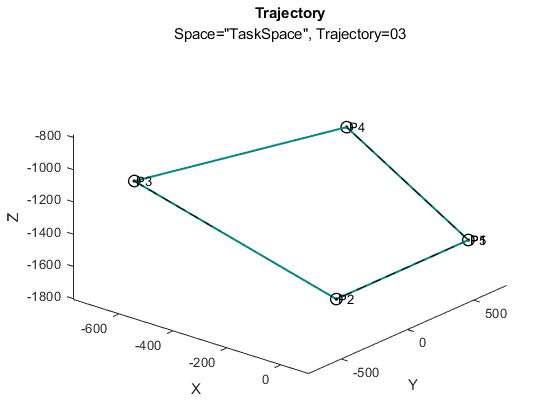

config.trajectory   = 3;

% Run simulation in Task Space
config.space        = enum.SpaceEnum.TaskSpace;
config.plotColor    = colors.blue;
[simOut_TS3, lastRun] = runSimulation(config, lastRun);


printlog('Done!', char(config.space));

[27-Sep-2021 23:01:08]: Done!


disp('========================================');

| Start simulation for "JointSpace"...  |
[27-Sep-2021 23:01:08]: Setting Variant Subsystem TP_MODE=2...
[27-Sep-2021 23:01:08]: Setting "StopTime"=20s...
[27-Sep-2021 23:01:08]: Setting "FastRestart"="off"... -> Compilation enabled:
* Current space differs from previous simulation ["JointSpace"~="TaskSpace"].
[27-Sep-2021 23:01:08]: Generating waypoints "gen_waypointSet_03"...
Waypoint set:
        1445        1445        1045        1045        1445
         500        -500        -600         600         500
          85          85        -615        -415          85

[27-Sep-2021 23:01:09]: Start simulation...
[27-Sep-2021 23:01:09]: Solve Inverse Kinematics in JointSpace...
[27-Sep-2021 23:01:16]: Run simulation...
[27-Sep-2021 23:03:31]: Stop simulation.
[27-Sep-2021 23:03:32]: Plotting waypoints and trajectory...


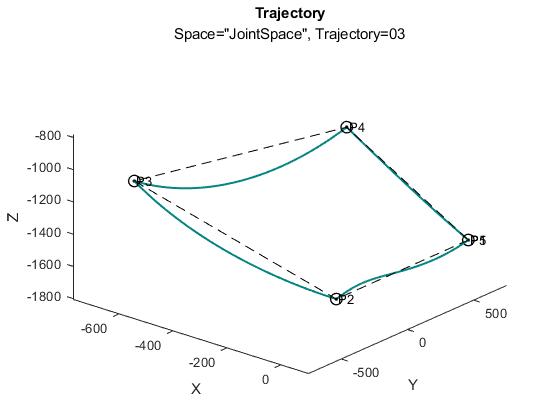


% Run simulation in Joint Space
config.space        = enum.SpaceEnum.JointSpace;
config.plotColor    = colors.blue;
[simOut_JS3, lastRun] = runSimulation(config, lastRun);


printlog('Done!', char(config.space));

[27-Sep-2021 23:03:33]: Done!


disp('========================================');

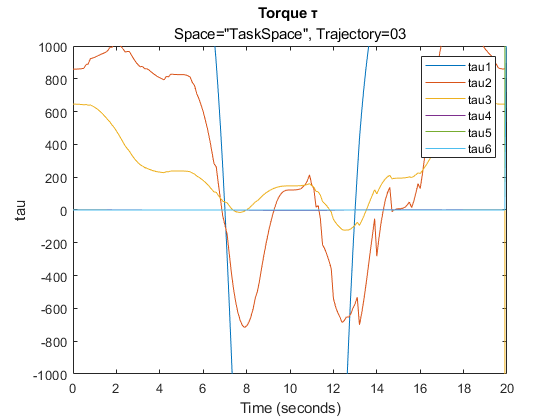


% plot torques
figure;
plotTorque(char(enum.SpaceEnum.TaskSpace), config.trajectory, simOut_TS3.logsout.getElement('tau').Values);

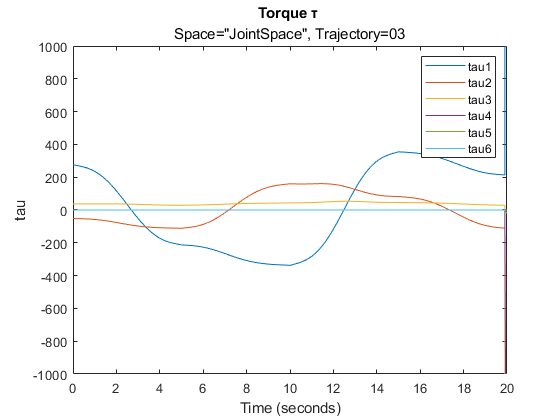

figure;
plotTorque(char(enum.SpaceEnum.JointSpace), config.trajectory, simOut_JS3.logsout.getElement('tau').Values);

### **Simulate TaskSpace - gen_02**

| Start simulation for "TaskSpace"...  |
[27-Sep-2021 23:03:39]: Setting Variant Subsystem TP_MODE=1...
[27-Sep-2021 23:03:39]: Setting "StopTime"=30s...
[27-Sep-2021 23:03:39]: Setting "FastRestart"="off"... -> Compilation enabled:
* Current trajectory differs from previous simulation ["2"~="3"].
* Current space differs from previous simulation ["TaskSpace"~="JointSpace"].
* Current waypoints differs from previous simulation.
[27-Sep-2021 23:03:39]: Generating waypoints "gen_waypointSet_02"...
Waypoint set:
        1345         895         895        1395        1445        1445        1345
           0           0        -500         100         200        -100           0
        -315        -165         185         435        -765        -365        -315

[27-Sep-2021 23:03:41]: Start simulation...
[27-Sep-2021 23:03:41]: Run simulation...
[27-Sep-2021 23:06:14]: Stop simulation.
[27-Sep-2021 23:06:15

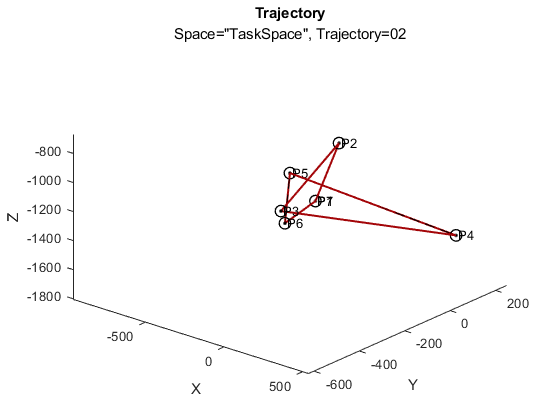

config.trajectory   = 2;
config.space        = enum.SpaceEnum.TaskSpace;
config.plotColor    = colors.red;
[simOutTS, lastRun] = runSimulation(config, lastRun);


printlog('Done!', char(config.space));

[27-Sep-2021 23:06:16]: Done!


disp('========================================');

### **Simulate JointSpace [Cubic] - gen_02**

| Start simulation for "JointSpace"...  |
[28-Sep-2021 00:02:32]: Setting Variant Subsystem TP_MODE=2...
[28-Sep-2021 00:02:32]: Setting "StopTime"=30s...
[28-Sep-2021 00:02:32]: Setting "FastRestart"="off"... -> Compilation enabled:
[28-Sep-2021 00:02:32]: Setting TrajectoryGenerator "PolynomialMethod"="Quintic Polynomial"...
* Current polynomial differs from previous simulation ["Quintic Polynomial"~="Cubic Polynomial"].
[28-Sep-2021 00:02:32]: Generating waypoints "gen_waypointSet_02"...
Waypoint set:
        1345         895         895        1395        1445        1445        1345
           0           0        -500         100         200        -100           0
        -315        -165         185         435        -765        -365        -315

[28-Sep-2021 00:02:33]: Start simulation...
[28-Sep-2021 00:02:33]: Solve Inverse Kinematics in JointSpace...
[28-Sep-2021 00:02:40]: Run simulation...


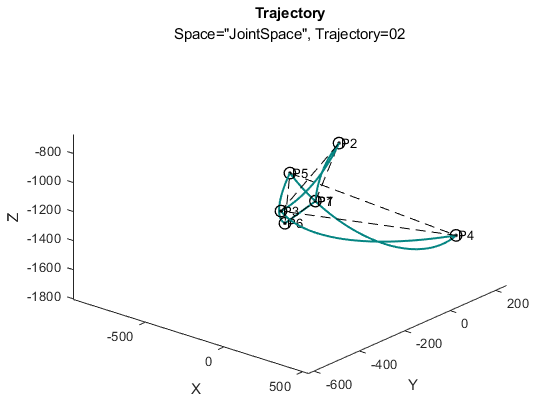

config.space        = enum.SpaceEnum.JointSpace;
config.plotColor    = colors.blue;
config.polynomial   = "Quintic Polynomial";

[simOutJSC, lastRun] = runSimulation(config, lastRun);


printlog('Done!', char(config.space));

[28-Sep-2021 00:05:05]: Done!


disp('========================================');

### **Simulate JointSpace [Quintic] - gen_02**

| Start simulation for "JointSpace"...  |
[28-Sep-2021 00:05:05]: Setting Variant Subsystem TP_MODE=2...
[28-Sep-2021 00:05:05]: Setting "StopTime"=30s...
[28-Sep-2021 00:05:05]: Setting "FastRestart"="off"... -> Compilation enabled:
[28-Sep-2021 00:05:05]: Setting TrajectoryGenerator "PolynomialMethod"="Cubic Polynomial"...
* Current polynomial differs from previous simulation ["Cubic Polynomial"~="Quintic Polynomial"].
[28-Sep-2021 00:05:05]: Generating waypoints "gen_waypointSet_02"...
Waypoint set:
        1345         895         895        1395        1445        1445        1345
           0           0        -500         100         200        -100           0
        -315        -165         185         435        -765        -365        -315

[28-Sep-2021 00:05:06]: Start simulation...
[28-Sep-2021 00:05:06]: Solve Inverse Kinematics in JointSpace...
[28-Sep-2021 00:05:11]: Run simulation...
[2

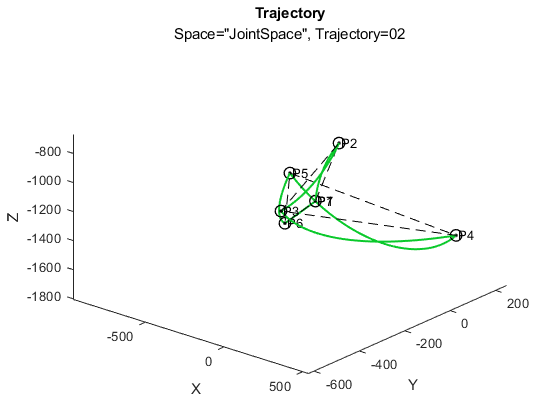

config.space        = enum.SpaceEnum.JointSpace;
config.plotColor    = colors.green;
config.polynomial   = "Cubic Polynomial";
[simOutJSQ, lastRun] = runSimulation(config, lastRun);


printlog('Done!', char(config.space));

[28-Sep-2021 00:07:50]: Done!


disp('=================================================');

### Compare joint angles trajectories** - gen_02**

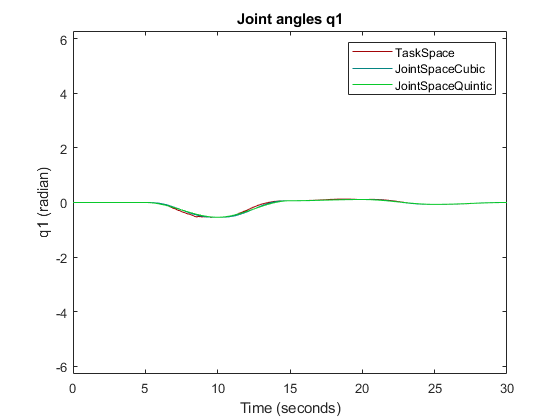

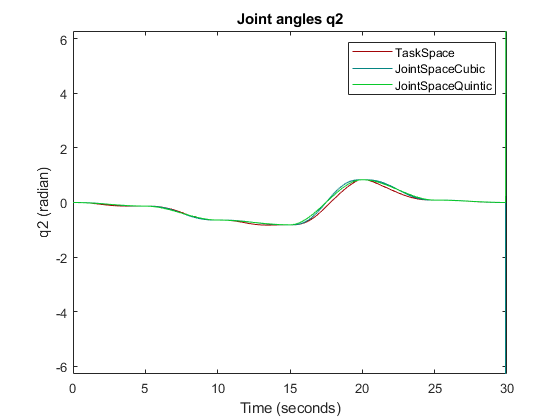

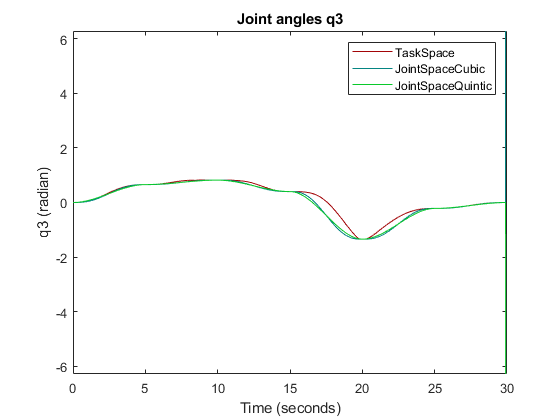

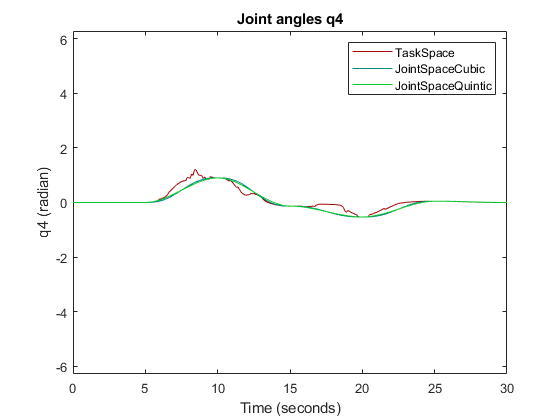

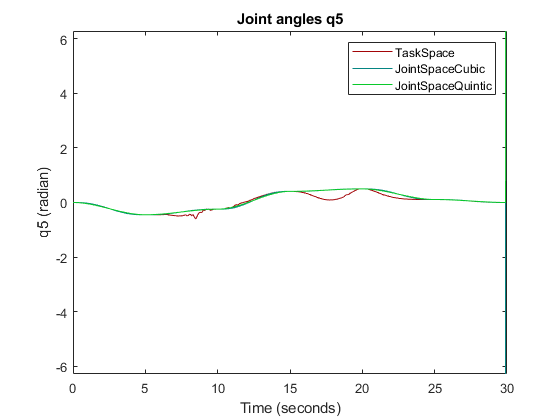

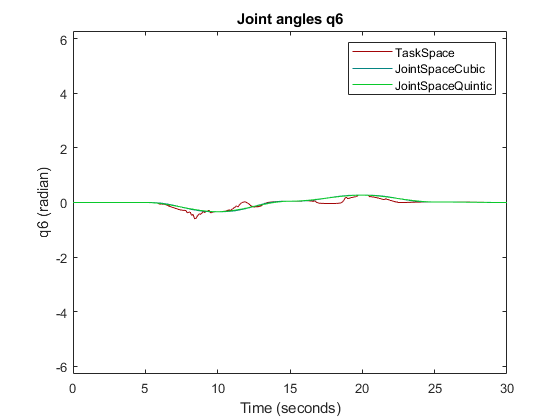

singlePlot = false;
verticalAlignment = false;

qT  = simOutTS.logsout.getElement('q').Values;
qJC = simOutJSC.logsout.getElement('q').Values;
qJQ = simOutJSQ.logsout.getElement('q').Values;
joints = fieldnames(qT);

if singlePlot
    figure; hold on;
end
for i=1:numel(joints)
    if ~singlePlot
        figure;
    elseif verticalAlignment
        subplot(6, 1, i);
    else
        subplot(3, 2, i);
    end
    plot(qT.(joints{i}), "Color", colors.red); hold on;
    plot(qJC.(joints{i}), "Color", colors.blue);
    plot(qJQ.(joints{i}), "Color", colors.green);
    ylim([-2*pi, 2*pi]);
    legend(char(enum.SpaceEnum.TaskSpace), ...
        sprintf('%s%s', char(enum.SpaceEnum.JointSpace), 'Cubic'), ...
        sprintf('%s%s', char(enum.SpaceEnum.JointSpace), 'Quintic'));
    title(sprintf('Joint angles %s', joints{i}));
end

The joint space trajectory in red is generally smoothier than the blue one, which is task-based. In the plot of the joint "q4" and "q5" the slope of the curves can be noticed: the slope for the trajectory in the task space is pretty higher (that means more actuator motion in general) than the one joint-based.

### Compare torques** - gen_02**

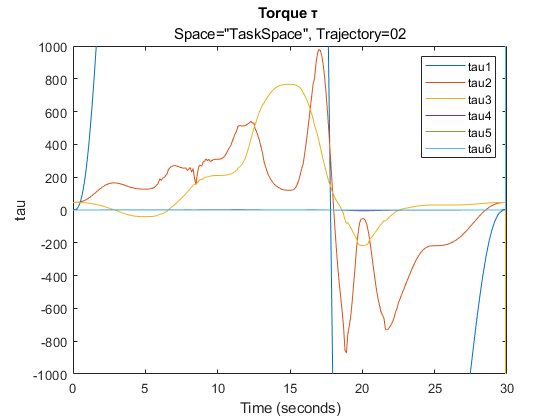

% plot torques
figure;
plotTorque(char(enum.SpaceEnum.TaskSpace), config.trajectory, simOutTS.logsout.getElement('tau').Values);

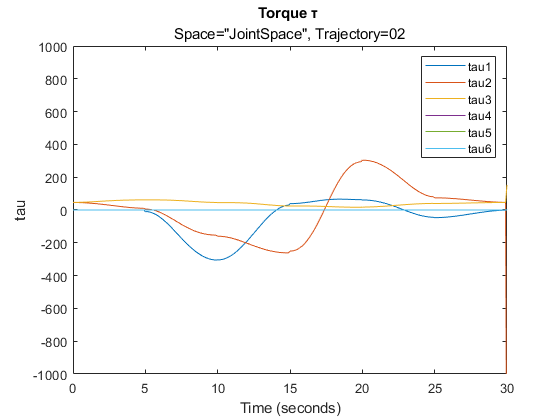

figure;
plotTorque(char(enum.SpaceEnum.JointSpace), config.trajectory, simOutJSQ.logsout.getElement('tau').Values);

### Run task in Joint Space - gen_05

| Start simulation for "JointSpace"...  |
[28-Sep-2021 00:09:20]: Setting Variant Subsystem TP_MODE=2...
[28-Sep-2021 00:09:20]: Setting "StopTime"=35s...
[28-Sep-2021 00:09:20]: Setting "FastRestart"="off"... -> Compilation enabled:
* Current trajectory differs from previous simulation ["5"~="2"].
* Current waypoints differs from previous simulation.
[28-Sep-2021 00:09:20]: Generating waypoints "gen_waypointSet_05"...
Waypoint set:
        1345        1295        1045        1145        1145        1045        1295        1345
           0       -1200        -750        -100         100         750        1200           0
        -315          85         485        -415        -415         485          85        -315

[28-Sep-2021 00:09:21]: Start simulation...
[28-Sep-2021 00:09:21]: Solve Inverse Kinematics in JointSpace...
[28-Sep-2021 00:09:24]: Run simulation...
[28-Sep-2021 00:11:54]: Stop simulati

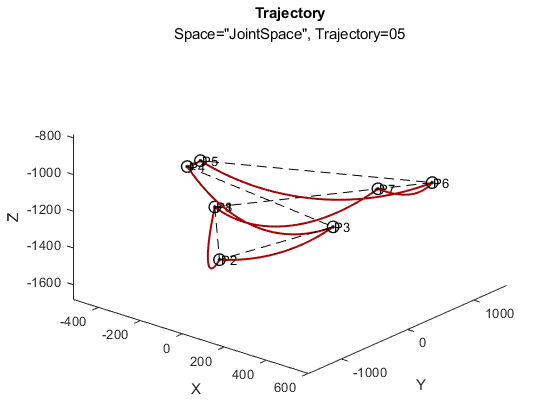

% configure
config.trajectory   = 5;
config.space        = enum.SpaceEnum.JointSpace;
config.plotColor    = colors.red;
% run the simulation
[simOutJS05, lastRun] = runSimulation(config, lastRun);

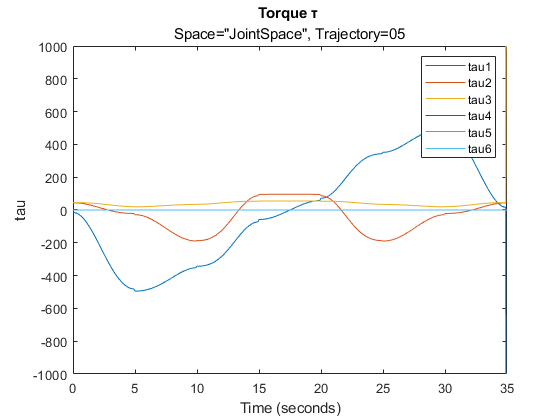

% plot the torque
figure;
plotTorque(char(enum.SpaceEnum.JointSpace), config.trajectory, simOutJS05.logsout.getElement('tau').Values);

function [simOut, lastRun] = runSimulation(config, lastRun)
disp('========================================');
fprintf('| Start simulation for "%s"...  |\n', config.space.char());
disp('========================================');
assignin("base", 'TP_MODE', double(config.space))
printlog('Setting Variant Subsystem TP_MODE=%d...', double(config.space));

if config.visualize
    open('KukaKR6__.wrl');
end

% start simulation
[~, waypointsStruct] = enableFastRestartIfPossible(config.modelName, lastRun, config);
printlog('Generating waypoints "gen_waypointSet_%02d"...', config.trajectory);
assignin("base", 'waypointsStruct', waypointsStruct);
disp('Waypoint set:'); disp(waypointsStruct.waypoints);

warning('off', 'MATLAB:system:saveObjectImplNotImplemented');
simOut = sim(config.modelName);

% get trajectory information
varName = sprintf('pos_%s', char(config.space));
simOutTrajectory = reshape(simOut.logsout.getElement(varName).Values.Data(:, 6, 1:end-1), ...
    3, numel(simOut.tout)-1);
% plot trajectory
printlog('Plotting waypoints and trajectory...');
figure; hold on;
plotWaypoints(waypointsStruct.waypoints, simOutTrajectory, config.plotColor);
title('Trajectory', sprintf('Space="%s", Trajectory=%02d', char(config.space), config.trajectory));
view(40, 35);

% save information of current simulation
lastRun = struct( ...
    'polynomial', config.polynomial, ...
    'space', config.space, ...
    'trajectory', config.trajectory, ...
    'waypoints', waypointsStruct);
end

function plotTorque(spaceName, trajectory, simOutTorques)
    plot(simOutTorques);
    legend('tau1', 'tau2', 'tau3', 'tau4', 'tau5', 'tau6');
    ylim([-1000, 1000]);
    title('Torque τ ', sprintf('Space="%s", Trajectory=%02d', char(spaceName), trajectory));
end

function v = cosi(x) 
v = cos(x); if abs(v) < eps, v = 0; end
end
function v = sini(x) 
v = sin(x); if abs(v) < eps, v = 0; end 
end

## Bibliography

[1] T. Sugihara, "Solvability-unconcerned inverse kinematics based on Levenberg-Marquardt method with robust damping," *2009 9th IEEE-RAS International Conference on Humanoid Robots*, 2009, pp. 555-560, doi: 10.1109/ICHR.2009.5379515.

[2] K. Ofjall and M. Felsberg,  "Rapid explorative direct inverse kinematics learning of relevant locations for active vision," in *2013 IEEE Workshop on Robot Vision (WORV 2013)*, Clearwater Beach, FL, 2013 pp. 14-19. doi: 10.1109/WORV.2013.6521932

[3] [https://people.duke.edu/~hpgavin/ce281/lm.pdf](https://people.duke.edu/~hpgavin/ce281/lm.pdf)

[4] [https://modernrobotics.northwestern.edu/nu-gm-book-resource/8-3-newton-euler-inverse-dynamics/](https://modernrobotics.northwestern.edu/nu-gm-book-resource/8-3-newton-euler-inverse-dynamics/)

[5] Roy, F., "Inverse Dynamics - The Recursive Newton-Euler Method.", Springer US, 1987, pp. 65-77, doi: 10.1007/978-0-387-74315-8_4